clear; clc;
addpath('tdoa');

d = 2.0; dists = 100;
x1 = [0.0, 0.0];
x1p = [0, d];
x1m = [0, -d];
x2 = [dists, 0.0];
x3 = [-dists, 0.0];
p = [60.0, 20.0];

d1 = norm(x1-p,2);
d1p = norm(x1p-p,2);
d1m = norm(x1m-p,2);

d2 = norm(x2-p,2);
d3 = norm(x3-p,2);

h1 = hyperbola(d1-d2, x1, x2);

Hyperbola with totally 399978 points generated.


h11p = hyperbola(d1 - d2, x1p, x2);

Hyperbola with totally 399978 points generated.


h11m = hyperbola(d1 - d2, x1m, x2);

Hyperbola with totally 399978 points generated.


h1p = hyperbola(d1-d2 + 900/1000, x1, x2);

Hyperbola with totally 399978 points generated.


h1m = hyperbola(d1-d2 - 900/1000, x1, x2);

Hyperbola with totally 399978 points generated.



h2 = hyperbola(d1-d3, x1, x3);

Hyperbola with totally 400000 points generated.


h21p = hyperbola(d1 - d3, x1p, x3);

Hyperbola with totally 400000 points generated.


h21m = hyperbola(d1 - d3, x1m, x3);

Hyperbola with totally 400000 points generated.


h2p = hyperbola(d1-d3 + 900/1000, x1, x3);

Hyperbola with totally 400000 points generated.


h2m = hyperbola(d1-d3 - 900/1000, x1, x3);

Hyperbola with totally 400000 points generated.


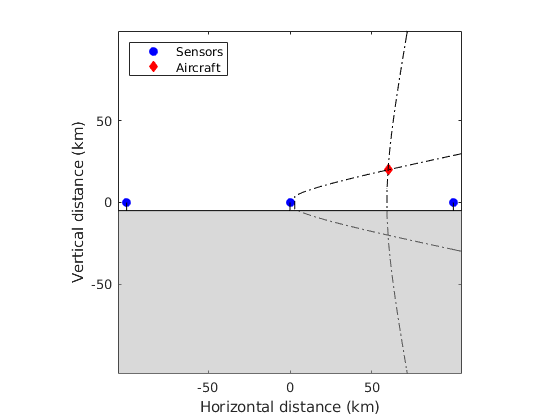

figure();
set(gca,'BoxStyle', 'full');
set(gca,'fontname','times')

xticks([-50, 0, 50]);
yticks([-50, 0, 50]);

hold on; box on; axis equal;
plot([x1(1),x2(1),x3(1)],[x1(2),x2(2),x3(2)],'bo','MarkerFaceColor','b');
plot(p(1),p(2),'rd','MarkerFaceColor','r');
% plot(x1p(1), x1p(2), 'bo', 'LineStyle',"--");
% plot(x1m(1), x1m(2), 'bo', 'LineStyle',"--");
% First hyperbola
plot(h1(1,:), h1(2,:), 'Color',[0 0 0],'LineStyle',"-.");
% Second hyperbola
plot(h2(1,:), h2(2,:), 'Color',[0 0 0],'LineStyle',"-.");
% Error Hyperbolas
% plot(h11p(1,:),h11p(2,:),'Color',[0 0 0],'LineStyle',"--");
% plot(h11m(1,:),h11m(2,:),'Color',[0 0 0],'LineStyle',"--");
% plot(h21p(1,:),h21p(2,:),'Color',[0 0 0],'LineStyle',"--");
% plot(h21m(1,:),h21m(2,:),'Color',[0 0 0],'LineStyle',"--");

% Ground
plot([-310, 310],[-5,-5],'k-');
plot([x1(1),x1(1)],[x1(2),-5],'k-');
plot([x2(1),x2(1)],[x2(2),-5],'k-');
plot([x3(1),x3(1)],[x3(2),-5],'k-');

fill([-310,-310,310,310],[-5,-200,-200,-5],[0.7,0.7,0.7],'FaceAlpha',0.5);

% Plot
legend('Sensors','Aircraft','Location',"northwest");
xlabel('Horizontal distance (km)',"FontName",'times'); ylabel('Vertical distance (km)');
xlim([-105, 105]); ylim([-105, 105]);
hold off;

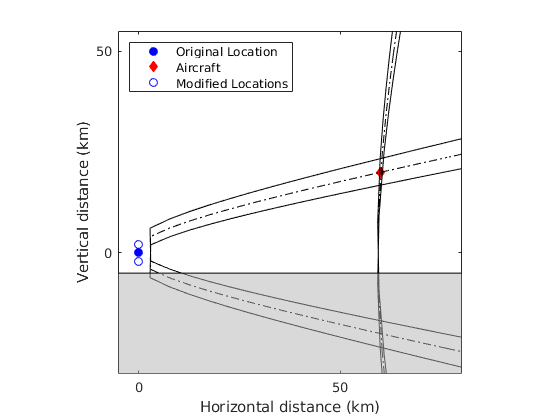

figure();
set(gca,'BoxStyle', 'full');
set(gca,'fontname','times')

xticks([-50, 0, 50]);
yticks([-50, 0, 50]);

hold on; box on; axis equal;
plot([x1(1),x2(1),x3(1)],[x1(2),x2(2),x3(2)],'bo','MarkerFaceColor','b');
plot(p(1),p(2),'rd','MarkerFaceColor','r');
plot([x1p(1),x1m(1)], [x1p(2),x1m(2)], 'bo');
% First hyperbola
plot(h1(1,:), h1(2,:), 'Color',[0 0 0],'LineStyle',"-.");
% Second hyperbola
plot(h2(1,:), h2(2,:), 'Color',[0 0 0],'LineStyle',"-.");
% Error Hyperbolas
plot(h11p(1,:),h11p(2,:),'Color',[0 0 0],'LineStyle',"-");
plot(h11m(1,:),h11m(2,:),'Color',[0 0 0],'LineStyle',"-");
plot(h21p(1,:),h21p(2,:),'Color',[0 0 0],'LineStyle',"-");
plot(h21m(1,:),h21m(2,:),'Color',[0 0 0],'LineStyle',"-");

% Ground
plot([-310, 310],[-5,-5],'k-');
% plot([x1(1),x1(1)],[x1(2),-5],'k-');
plot([x2(1),x2(1)],[x2(2),-5],'k-');
plot([x3(1),x3(1)],[x3(2),-5],'k-');

fill([-310,-310,310,310],[-5,-200,-200,-5],[0.7,0.7,0.7],'FaceAlpha',0.5);

% Plot
legend('Original Location','Aircraft','Modified Locations','Location',"northwest");
xlabel('Horizontal distance (km)',"FontName",'times'); ylabel('Vertical distance (km)');
xlim([-5 80]); ylim([-30 55]);
hold off;

x1p = [d, 0];
x1m = [-d, 0];
d1p = norm(x1p-p,2);
d1m = norm(x1m-p,2);

h1 = hyperbola(d1-d2, x1, x2);

Hyperbola with totally 399978 points generated.


h11p = hyperbola(d1 - d2, x1p, x2);

Hyperbola with totally 399978 points generated.


h11m = hyperbola(d1 - d2, x1m, x2);

Hyperbola with totally 399976 points generated.



h2 = hyperbola(d1-d3, x1, x3);

Hyperbola with totally 400000 points generated.


h21p = hyperbola(d1 - d3, x1p, x3);

Hyperbola with totally 400000 points generated.


h21m = hyperbola(d1 - d3, x1m, x3);

Hyperbola with totally 400000 points generated.


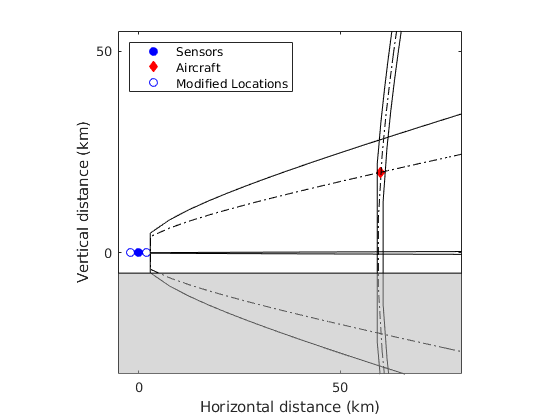

figure();
set(gca,'BoxStyle', 'full');
set(gca,'fontname','times')

xticks([-50, 0, 50]);
yticks([-50, 0, 50]);

hold on; box on; axis square
plot([x1(1),x2(1),x3(1)],[x1(2),x2(2),x3(2)],'bo','MarkerFaceColor','b');
plot(p(1),p(2),'rd','MarkerFaceColor','r');
plot([x1p(1),x1m(1)], [x1p(2),x1m(2)], 'bo');
% First hyperbola
plot(h1(1,:), h1(2,:), 'Color',[0 0 0],'LineStyle',"-.");
% Second hyperbola
plot(h2(1,:), h2(2,:), 'Color',[0 0 0],'LineStyle',"-.");
% Error Hyperbolas
plot(h11p(1,:),h11p(2,:),'Color',[0 0 0],'LineStyle',"-");
plot(h11m(1,:),h11m(2,:),'Color',[0 0 0],'LineStyle',"-");
plot(h21p(1,:),h21p(2,:),'Color',[0 0 0],'LineStyle',"-");
plot(h21m(1,:),h21m(2,:),'Color',[0 0 0],'LineStyle',"-");

% Ground
plot([-310, 310],[-5,-5],'k-');
% plot([x1(1),x1(1)],[x1(2),-5],'k-');
plot([x2(1),x2(1)],[x2(2),-5],'k-');
plot([x3(1),x3(1)],[x3(2),-5],'k-');

% Plot
fill([-310,-310,310,310],[-5,-200,-200,-5],[0.7,0.7,0.7],'FaceAlpha',0.5);
legend('Sensors','Aircraft','Modified Locations','Location',"northwest");
xlabel('Horizontal distance (km)',"FontName",'times'); ylabel('Vertical distance (km)');
xlim([-5 80]); ylim([-30 55]);

hold off;

%% Previous versions

figure();
set(gca,'XTick',[],'YTick',[], 'BoxStyle', 'full');
set(gca,'fontname','times')

hold on; box on; axis equal
plot(x1(1),x1(2),'bo','MarkerFaceColor','b');
plot(x2(1), x2(2), 'bo','MarkerFaceColor','b');
plot(x3(1),x3(2), 'ko','MarkerFaceColor','b');
plot(p(1), p(2), 'rd','MarkerFaceColor',"r");
% First hyperbola
plot(h1(1,:), h1(2,:), 'Color',[0 0 0]);
plot(h1p(1,:), h1p(2,:), 'Color',[0 0 0], 'LineStyle',"--");
plot(h1m(1,:), h1m(2,:), 'Color',[0 0 0], 'LineStyle',"--");
% Second hyperbola
plot(h2(1,:), h2(2,:), 'Color',[0 0 0]);
plot(h2p(1,:), h2p(2,:), 'Color',[0 0 0], 'LineStyle',"--");
plot(h2m(1,:), h2m(2,:), 'Color',[0 0 0], 'LineStyle',"--");

% Ground
plot([-310, 310],[-5,-5],'k-');
plot([x1(1),x1(1)],[x1(2),-5],'k-');
plot([x2(1),x2(1)],[x2(2),-5],'k-');
plot([x3(1),x3(1)],[x3(2),-5],'k-');

% Plot
xlabel('Horizontal distance',"FontName",'times'); ylabel('Vertical distance');
xlim([-310, 310]); ylim([-10, 200]);
hold off;

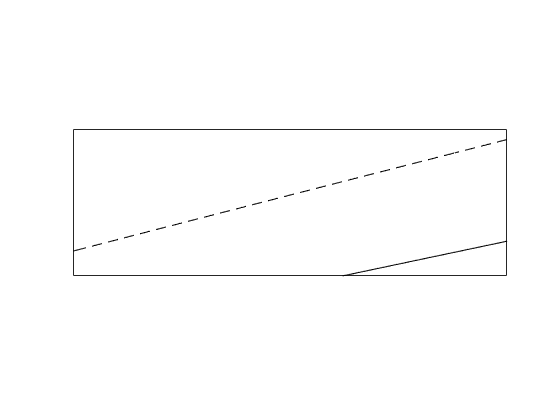

figure();
set(gca,'XTick',[],'YTick',[], 'BoxStyle', 'full');

hold on; box on; axis equal;
plot(x1(1),x1(2),'ko'); plot(x2(1), x2(2), 'ko'); plot(x3(1),x3(2), 'ko');
plot(p(1), p(2), 'rd','MarkerFaceColor',"r");
% First hyperbola
plot(h1(1,:), h1(2,:), 'Color',[0 0 0]);
plot(h1p(1,:), h1p(2,:), 'Color',[0 0 0], 'LineStyle',"--");
plot(h1m(1,:), h1m(2,:), 'Color',[0 0 0], 'LineStyle',"--");
% Second hyperbola
plot(h2(1,:), h2(2,:), 'Color',[0 0 0]);
plot(h2p(1,:), h2p(2,:), 'Color',[0 0 0], 'LineStyle',"--");
plot(h2m(1,:), h2m(2,:), 'Color',[0 0 0], 'LineStyle',"--");

% Ground
plot([-310, 310],[-5,-5],'k-');

% Plot
xlim([103.7 137.1])
ylim([34.0 45.3])
hold off;